# Optimize Design using AI Surrogate Model

This script demonstrates how to use optimization solvers to quickly search the AI surrogate models to identify optimal designs to meet design and performance criteria.

The workflow is summarized below:

## Optimization Background

The three main components of an optimization problem are:

- **Optimization variables**: There are the parameters whose values the optimization solver directly manipulates at each iteration.  These are also known as design variables or decision variables.

- **Objective function**: This is the metric that the optimization solver aims to either minimize or maximize, by manipulating the values of the optimization variables.  There can be multiple objective functions, in which case the problem is a multi-objective problem.

- **Constraints**: These limit the feasible design space.  For example, these can include lower and upper bounds on the optimization variables, linear inequality constraints on combinations of optimization variables, and lower or upper thresholds for performance metrics.

This demo uses the [Problem-Based Optimization Workflow](https://www.mathworks.com/help/optim/ug/problem-based-workflow.html) in MATLAB in formulate the optimization problem, in terms of these three components.

The first optimization problem solved in this example script is described as follows:

- Objective function: Minimize the L2-norm of the roll angle

- Optimization variables: The same set of parameters used for the AI model training

- Constraints: The same lower and upper bounds and linear constraints used for AI model training

## Load Parameter Data and AI Models

Recall that the parTableVal_trimSensitivity.mat file, generated by the Sensitivity Analysis step, defines the design parameters to use for the AI modeling and optimization.

Extract the parameter information from this file.  Use the extracted data to define the optimization variables, bounds, and default values.

% Load the parameter table
load parTableVal_trimSensitivity.mat parTableVal_trim;

% Call helper script to extract the needed data from the parameter table
% to define the optimization variables, bounds, and default values.
% Store the values in the workspace.
extractParamTableForOptim;

Choose a machine learning/deep learning model type to use, based on the AI model validation and comparison done in the Train Models step.  Load the model.

modelType = "gpModel";

% Call helper script that loads the AI model(s) as indicated by the aiModel
% selection.

loadAIModelForOptim;

## Define Parameters to Optimize

Define an array of optimization variables, using the variable names, lower bounds, and upper bounds extracted from the parameter table.

designVars = optimvar("designVars",designVarNames',"LowerBound",designVarsMin,...
    "UpperBound",designVarsMax);

Use the default variable values extracted from the parameter table to define an initial point for the optimization solvers.  Note that this initial point is not required/used by all solvers.

initialPoint.designVars = designVarsDef;

## Define Design Objective

The two performance metrics predicted by the AI models are:

- Roll metric

- Ride metric

For this first optimization problem, the objective is to minimize the roll metric.  The ride metric is considered in subsequent optimization problems.

To use AI models for the objective function and constraints:

- Wrapper functions for the "predict" function are defined below as local functions.  The "predict" function provides predicted values form the AI models.

- The wrapper functions are converted to optimization expressions.

- These optimization expressions can then be used for the objective function, and/or any constraints.

The local wrapper function for an AI model is shown below:

function response = predResponse(designVariables,model)
% Returns predicted response value, given an AI model and row of design
% variable values

responsePredict = predict(model,designVariables);

% Ensure response value is a double.  Deep learning model predictions
% return as single, but optimization solvers expect double.
response = double(responsePredict);

end

Convert AI model prediction wrapper functions to optimization expressions.  Ensure consistency in response variable assignments.

if useMultiOutputModel == 1 % Multi-response model
       
    % Determine the indices for RollMetric and RideMetric
    % in the multi-response model
    rollIdx = strcmp(responseVarNames, "RollMetric");
    rideIdx = strcmp(responseVarNames, "RideMetric");

    predictExpr = fcn2optimexpr(@predResponse,designVars,multiOutModel,'ReuseEvaluation',true);

    ridePredict = predictExpr(rideIdx);
    rollPredict = predictExpr(rollIdx);

else % Single-response models

    % Create optimization expressions for each metric, checking against the
    % response variable name
    if strcmp(responseVarNames(1),"RollMetric") & strcmp(responseVarNames(2),"RideMetric")
        rollPredict = fcn2optimexpr(@predResponse,designVars,singleOutModel1);
        ridePredict = fcn2optimexpr(@predResponse,designVars,singleOutModel2);
    elseif strcmp(responseVarNames(1),"RideMetric") & strcmp(responseVarNames(2),"RollMetric")
        ridePredict = fcn2optimexpr(@predResponse,designVars,singleOutModel1);
        rollPredict = fcn2optimexpr(@predResponse,designVars,singleOutModel2);
    end

end

Create the optimization problem object and assign the optimization expression for the roll metric as the objective function.

By default, optimization problems are configured to minimize the objective function.  The ObjectiveSense is set here explicitly for clarity.

% Create problem
rollProb = optimproblem;

autosolver = "fmincon"

validsolvers = 1×6 string array
    "fmincon"    "ga"    "patternsearch"    "surrogateopt"    "gamultiobj"    "paretosearch"



% Define problem objective
rollProb.Objective = rollPredict;
rollProb.ObjectiveSense = 'min';

## Add Constraints

The optimization variables have already been defined with lower and upper bound constraints.

As described in previous workflow steps, additional restrictions on HP_A1_Ro_Inbz and HP_A1_Ro_Outz are needed to limit the tie rod angle to within a reasonable range.  Specifically:

-0.05 <= HP_A1_Ro_Inbz - HP_A1_Ro_Outz <= 0.04

If both of these parameters are included as design variables for the optimization, implement this restriction as a set of linear inequality constraints.

If only of these parameters is included as a design variable, implement this restriction by modifying the lower and upper bound of the design variable accordingly.


Solving problem using patternsearch.
patternsearch stopped because the mesh size was less than options.MeshTolerance.


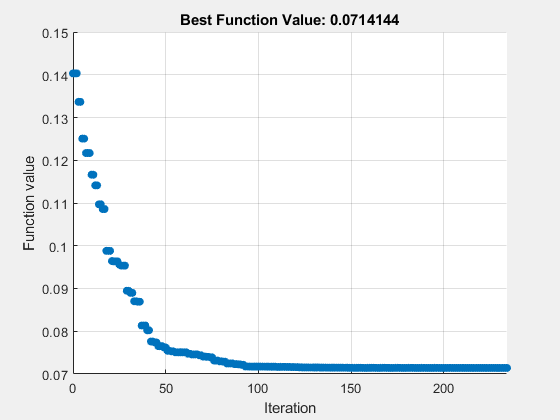

solution_roll = struct with fields:
    designVars: [0.1886 0.1550 -0.2500 0.5000 0.2000 0.6560 0.1000 0.2500 0.1000 0.6500]


optRollPred_roll = 0.0714

exitFlag_roll =     SolverConvergedSuccessfully


% If both parameters are optimization variables, implement as linear
% inequality constraints
if any(strcmp(designVarNames,"HP_A1_Ro_Inbz")) && any(strcmp(designVarNames,"HP_A1_Ro_Outz"))
    % Constraint expressions are assigned as constraints in the
    % optimization problem

    rollProb.Constraints.tierodAngleMin = ...

Elapsed time is 10.949445 seconds.


        designVars("HP_A1_Ro_Inbz") - designVars("HP_A1_Ro_Outz") >= -0.05;
    rollProb.Constraints.tierodAngleMax = ...
        designVars("HP_A1_Ro_Inbz") - designVars("HP_A1_Ro_Outz") <= 0.04;

% If only one of the parameters is an optimization variable, implement as
% updated lower/upper bounds, if applicable

% If only HP_A1_Ro_Outz is part of the optimization variable
elseif ~any(strcmp(designVarNames,"HP_A1_Ro_Inbz")) && any(strcmp(designVarNames,"HP_A1_Ro_Outz"))
    % Calculate temporary bound values based on the above requirement
    tmpLower = paramsAllDef.HP_A1_Ro_Inbz - 0.04;
    tmpUpper = paramsAllDef.HP_A1_Ro_Inbz + 0.05;

    % Compare temporary and current bound values, and use the more
    % restrictive values
    designVars.LowerBound = max(designVars("HP_A1_Ro_Outz").LowerBound,tmpLower);
    designVars.UpperBound = min(designVars("HP_A1_Ro_Outz").UpperBound,tmpUpper);

% If only HP_A1_Ro_Inbz is part of the optimization variable
elseif any(strcmp(designVarNames,"HP_A1_Ro_Inbz")) && ~any(strcmp(designVarNames,"HP_A1_Ro_Outz"))

solutionsTable = 2×11 table
    Description    HP_A1_Ro_Inbz    HP_A1_Ro_Outz    HP_A1_AR_Inbx    HP_A2_UA_Outz    HP_A2_LA_inRz    HP_A2_LA_Outy    HP_A2_LA_Outz    HP_A2_AR_Inbx    HP_A2_AR_Outx    HP_A2_AR_Outy
    ___________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "Default"           0.205           0.185             -0.3            0.45             0.15             0.706            0.15              0.3               0.05            0.6     
    "Min Roll"        0.18858          

predResponseTable = 2×3 table
    Description    RideMetric    RollMetric
    ___________    __________    __________

    "Default"        1.0263        0.14033 
    "Min Roll"       1.2915       0.071414 


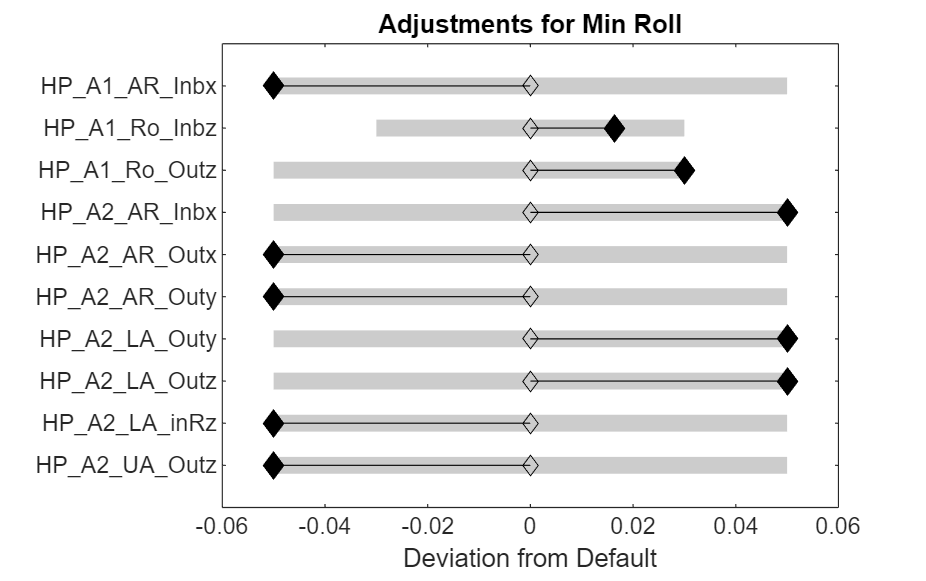

    % Calculate temporary bound values based on the above requirement
    tmpLower = paramsAllDef.HP_A1_Ro_Outz - 0.05;

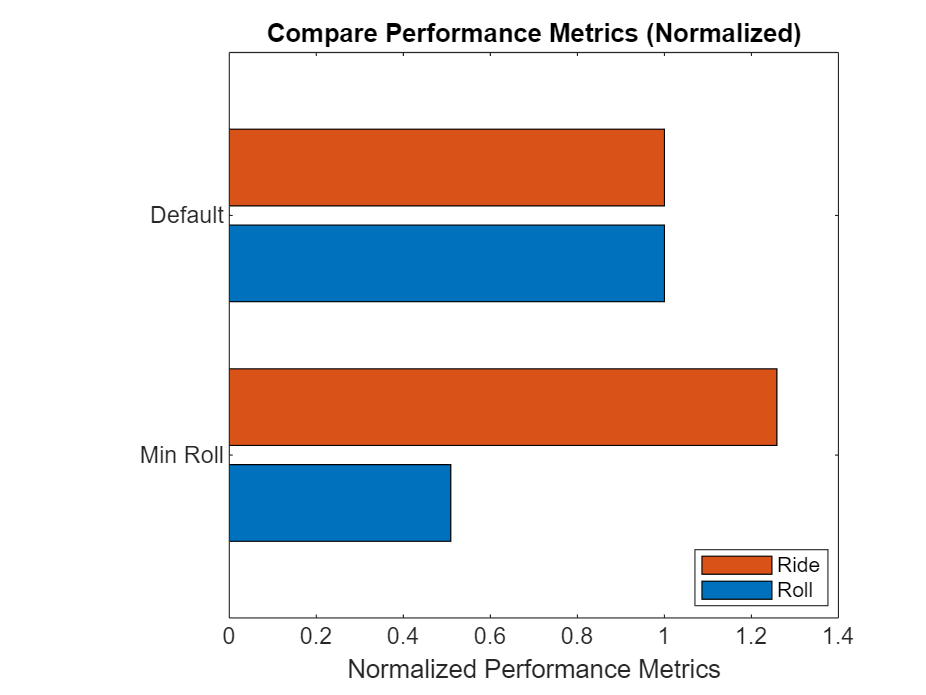

    tmpUpper = paramsAllDef.HP_A1_Ro_Outz + 0.04;


    % Compare temporary and current bound values, and use the more
    % restrictive values
    designVars.LowerBound = max(designVars("HP_A1_Ro_Inbz").LowerBound,tmpLower);
    designVars.UpperBound = min(designVars("HP_A1_Ro_Inbz").UpperBound,tmpUpper);
end

## Optimize Parameters

With the optimization variables, objective function, and constraints defined for the optimization problem, proceed to solving the problem.

Determine which solvers can be used to solve the defined optimization problem.

% Give the types of optimization variables, objective, and constraints
% defined in the optimization problem, the solver function determines the
% default and all other applicable solvers for the problem.
[autosolver,validsolvers] = solvers(rollProb)

2 parameter sets submitted, 2 obey parameter constraints.
 
 
2 simulations completed in 74.2851 seconds.
 
Of 2 tests, 2 were valid.


responseComparison = 2×3 table
               predResponseTable                   simResponseTable                predErrTable        
    _______________________________________    ________________________    ____________________________

    Description    RideMetric    RollMetric    RideMetric    RollMetric    Ride % Error    Roll % Error
    ___________    __________    __________    __________    __________    ____________    ____________
                                                                                                       
    "Default"        1.0263        0.14033       1.0269        0.14074       0.056619        0.29167   
    

Some things to consider when choosing between these solvers:

- fmincon is the default solver for the problem.  It is a local, gradient-based optimization solver, so the solution will depend on the initial point the solver starts with.

- patternsearch is a direct search solver that does not use gradients.  It requires more function evaluations that gradient-based solvers, but is more robust to noise and discontinuities.

- ga is a population-based global solver.  It requires many function calls to the objective function, but since acquiring prediction values from the AI models is so computationally inexpensive and fast, could be a feasible approach.  Specifying an additional hybrid function option tells the solver to run fmincon starting from the solution of ga, which can help further improve the solution.

- surrogateopt is more beneficial for optimization problems where the objective function is computationally expensive to compute.

- gamultiobj and paretosearch are multi-objective solvers.  They can be applied to solve single-objective problems, but they likely will be as efficient.

Pattern search is used here, as it provides good optimization results while solving quickly.  The user can experiment with different solvers as well.

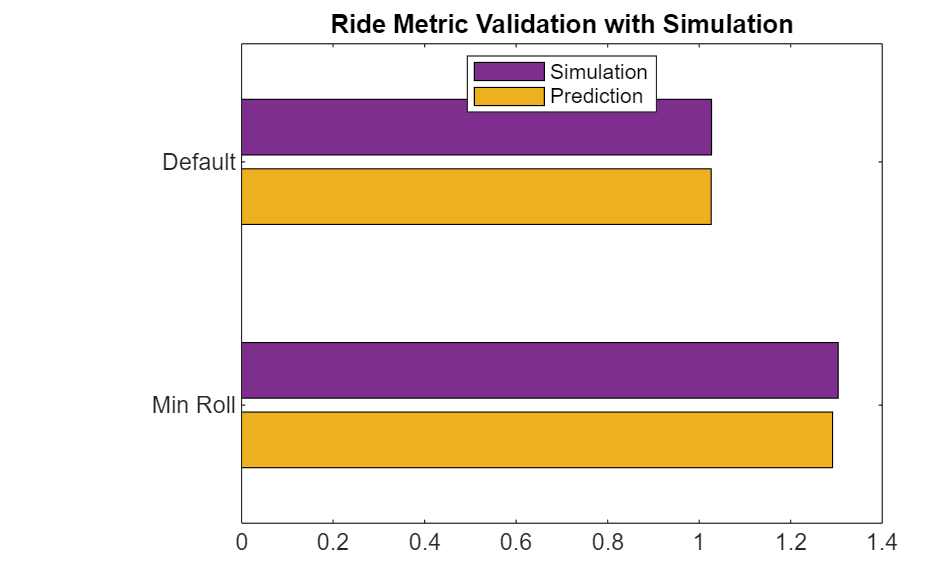

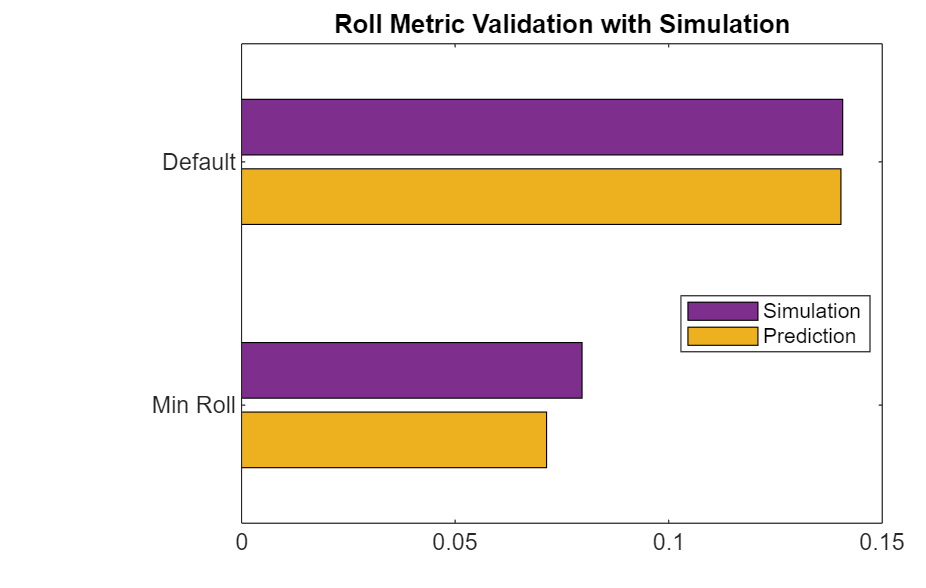

chosenSolver = 'patternsearch';

options_roll = optimoptions(chosenSolver,'Display','final',"PlotFcn","psplotbestf");

tic
[solution_roll,optRollPred_roll,exitFlag_roll] = solve(rollProb,initialPoint,...
    "Solver",chosenSolver,"Options",options_roll)
toc

Store the predicted solution and response values in a table.  New solutions from subsequent optimizations will be appended to these tables for comparison.


Solving problem using patternsearch.
patternsearch stopped because the mesh size was less than options.MeshTolerance.


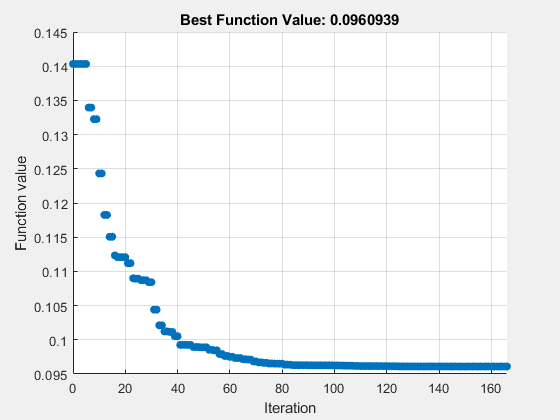

solution_modVar = struct with fields:
    designVars: [0.1950 0.1550 -0.2500 0.5000 0.1500 0.6560 0.1000 0.3000 0.1000 0.6500]


optRollPred_modVar = 0.0961

exitFlag_modVar =     SolverConvergedSuccessfully


Elapsed time is 7.964097 seconds.


% Call helper script to initialize empty tables for the solution and response values
initializeSolTables;

% Specify short description of this optimization problem for the table
descriptText = 'Default';

% Call helper function to add the solution and response values to the
% tables
[solutionsTable,predResponseTable] = addSolResptoTables(initialPoint,descriptText,solutionsTable,predResponseTable,designVarNames,...
    responseVarNames,rollPredict,ridePredict);

% Specify short description of this optimization problem for the table
descriptText = 'Min Roll';

% Call helper function to add the solution and response values to the
% tables
[solutionsTable,predResponseTable] = addSolResptoTables(solution_roll,descriptText,solutionsTable,predResponseTable,designVarNames,...
    responseVarNames,rollPredict,ridePredict)

Plot resulting design parameter values relative to the defaults.

suspOpt_Optimize_Design_plot_ParamAndDefault(solutionsTable(end,:))

solutionsTable = 3×11 table
        Description         HP_A1_Ro_Inbz    HP_A1_Ro_Outz    HP_A1_AR_Inbx    HP_A2_UA_Outz    HP_A2_LA_inRz    HP_A2_LA_Outy    HP_A2_LA_Outz    HP_A2_AR_Inbx    HP_A2_AR_Outx    HP_A2_AR_Outy
    ____________________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "Default"                    0.205           0.185             -0.3            0.45             0.15             0.706            0.15              0.3               0.05            0.6     
    "Min Rol

predResponseTable = 3×3 table
        Description         RideMetric    RollMetric
    ____________________    __________    __________

    "Default"                 1.0263        0.14033 
    "Min Roll"                1.2915       0.071414 
    "Min Roll, Lim Pars"      1.1962       0.096094 


Plot the predicted performance metrics for comparison.  The metrics are normalized by the default values.  The optimization found a solution that significantly reduces the roll metric, at the expense of the ride metric.

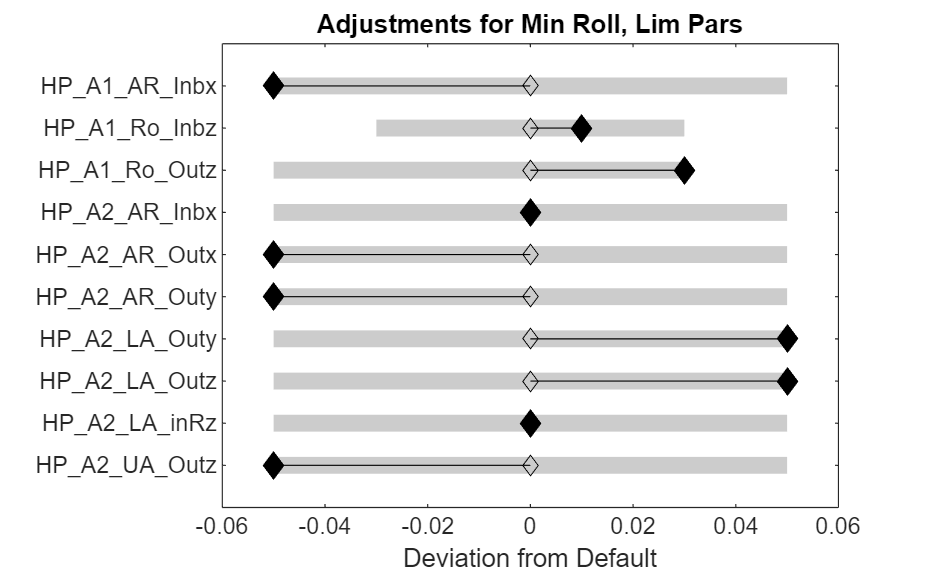

suspOpt_Optimize_Design_plot_MetricAndDefault(predResponseTable);

## Validate Solution Using Simulation

Validate the predicted performance of the optimization solution using Simscape simulation.

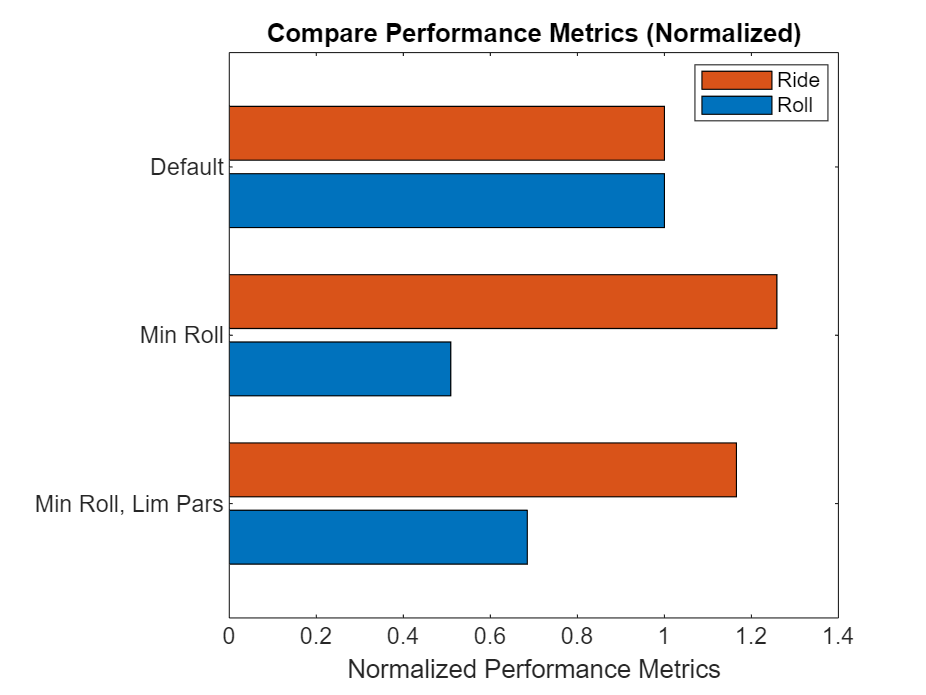

mdl = 'sm_car_dlc_only';


solIdx = 1:2;

[responseComparison,simResponseTable,predErrTable] = validateOptimSol(solutionsTable,...
    solIdx,paramsAllDef,designVarNames,mdl,Vehicle,parTableVal_trim,predResponseTable,simResponseTable,predErrTable);

1 parameter sets submitted, 1 obey parameter constraints.
 
 
1 simulations completed in 25.7996 seconds.
 
Of 1 tests, 1 were valid.


responseComparison = 3×3 table
                   predResponseTable                        simResponseTable                predErrTable        
    ________________________________________________    ________________________    ____________________________

        Description         RideMetric    RollMetric    RideMetric    RollMetric    Ride % Error    Roll % Error
    ____________________    __________    __________    __________    __________    ____________    ____________
                                                                                                                
    "Default"                 1.0263        0.14033       1.026

Plot predicted and simulated performance metrics for comparison.

The simulated values match reasonably well with the predicted values, indicating good accuracy from the AI model.

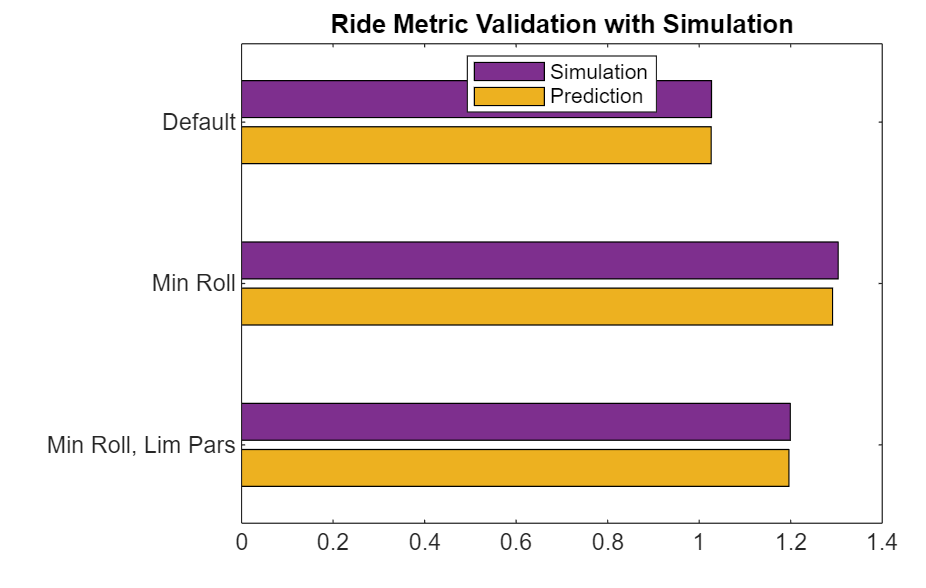

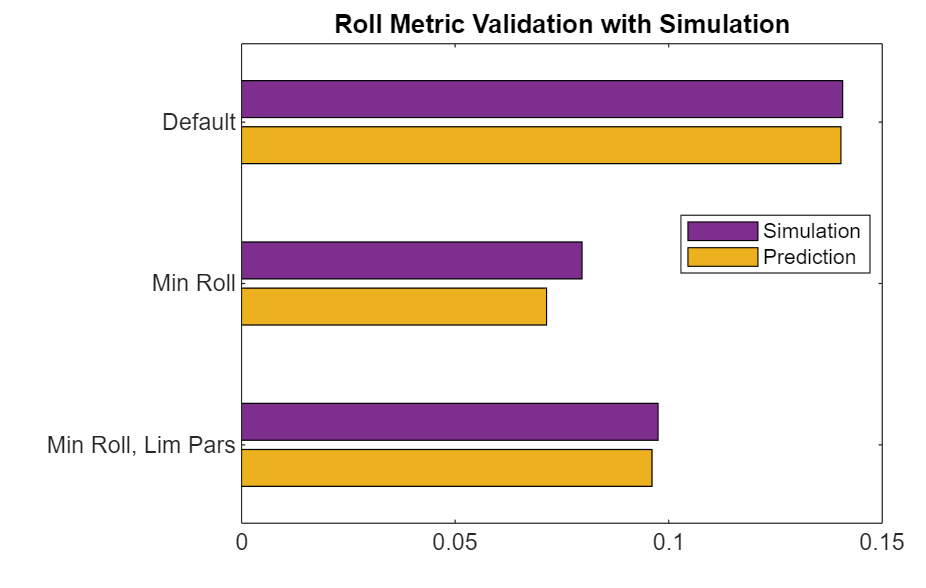

suspOpt_Optimize_Design_plot_MetricPredAndSim(responseComparison)

## Consider Different Design Scenarios

Since the AI surrogate models provide rapid predictions of the response values, new optimization problems with different formulations can be quickly run.  This is valuable for exploring what-if scenarios, as well as if requirements change and a new design solution is needed.

This script demonstrates how to modify the optimization problem formulation to address four example optimizations scenarios:

- Modifying the design variable bounds

- Adding a nonlinear constraint

- Combining multiple responses in single objective function

- Multi-objective optimization

### Modifying the Design Variable Bounds

Let's say we want to consider a scenario where:

- HP_A2_Ar_Inbx is fixed to 0.30, and

- HP_A2_LA_inRz lower and upper bounds are modified to 0.10 and 0.15, respectively

% Modify the bound values by indexing into the optimization variable using the variable
% names
designVars("HP_A2_AR_Inbx").LowerBound = 0.30;

ride2 = 1.2915

designVars("HP_A2_AR_Inbx").UpperBound = 0.30;

designVars("HP_A2_LA_inRz").LowerBound = 0.10;
designVars("HP_A2_LA_inRz").UpperBound = 0.15;

Solve the new optimization problem.  Since only the variable bounds have changed, use the same solver as before.

tic
[solution_modVar,optRollPred_modVar,exitFlag_modVar] = solve(rollProb,initialPoint,...
    "Solver",chosenSolver,"Options",options_roll)
toc

Add the new optimization solution to the solutions table and predicted responses table.


Solving problem using patternsearch.
Optimization finished: mesh size less than options.MeshTolerance 
and constraint violation is less than options.ConstraintTolerance.


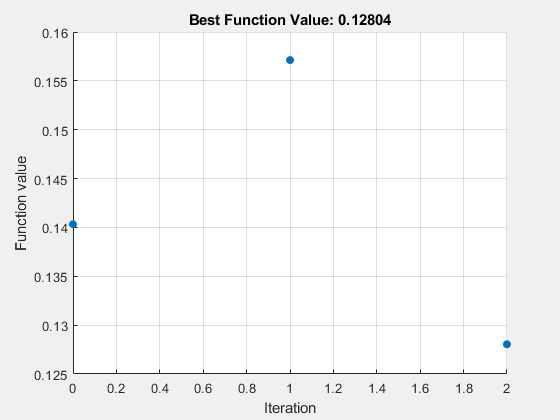

solution_rideCon = struct with fields:
    designVars: [0.2247 0.2000 -0.2504 0.4993 0.1500 0.7548 0.1008 0.3000 0.0408 0.5891]


optRoll_rideCon = 0.1280

exitFlag_rideCon =     SolverConvergedSuccessfully


% Specify short description of this optimization problem for the table
descriptText = 'Min Roll, Lim Pars';

% Call helper function to add the solution and response values to the

% tables

Elapsed time is 3.678523 seconds.


[solutionsTable,predResponseTable] = addSolResptoTables(solution_modVar,descriptText,solutionsTable,predResponseTable,designVarNames,...
    responseVarNames,rollPredict,ridePredict)

Plot resulting design parameter values relative to the defaults.

suspOpt_Optimize_Design_plot_ParamAndDefault(solutionsTable(end,:))

Plot normalized predicted performance metrics for comparison.

With the more restricted design space, the optimized roll metric has a higher value than the previous solution.

suspOpt_Optimize_Design_plot_MetricAndDefault(predResponseTable);

solutionsTable = 4×11 table
        Description         HP_A1_Ro_Inbz    HP_A1_Ro_Outz    HP_A1_AR_Inbx    HP_A2_UA_Outz    HP_A2_LA_inRz    HP_A2_LA_Outy    HP_A2_LA_Outz    HP_A2_AR_Inbx    HP_A2_AR_Outx    HP_A2_AR_Outy
    ____________________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "Default"                    0.205           0.185              -0.3             0.45           0.15              0.706             0.15            0.3               0.05              0.6   
    "Min Rol

predResponseTable = 4×3 table
        Description         RideMetric    RollMetric
    ____________________    __________    __________

    "Default"                 1.0263        0.14033 
    "Min Roll"                1.2915       0.071414 
    "Min Roll, Lim Pars"      1.1962       0.096094 
    "Min Roll, Lim Ride"     0.94767        0.12804 


Validate with simulation.

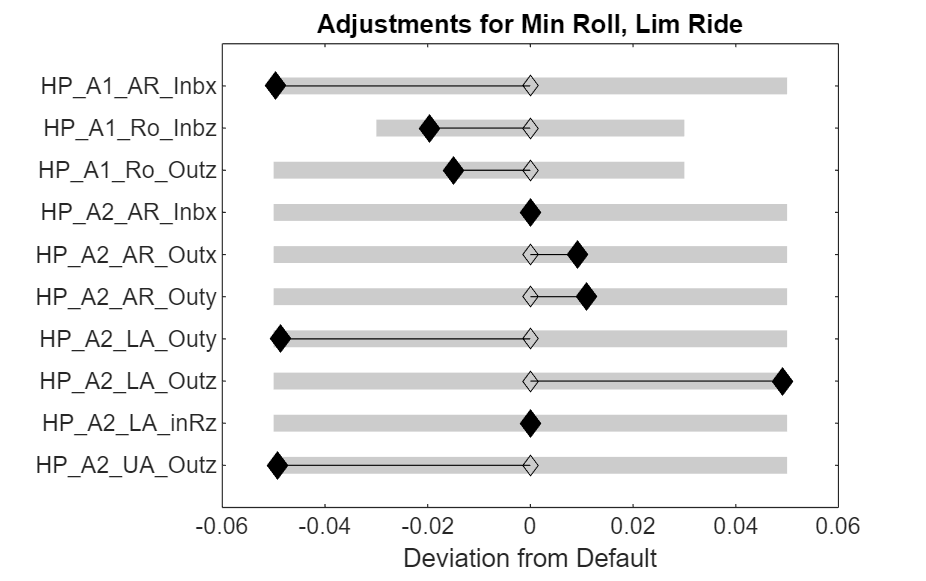

solIdx = 3;

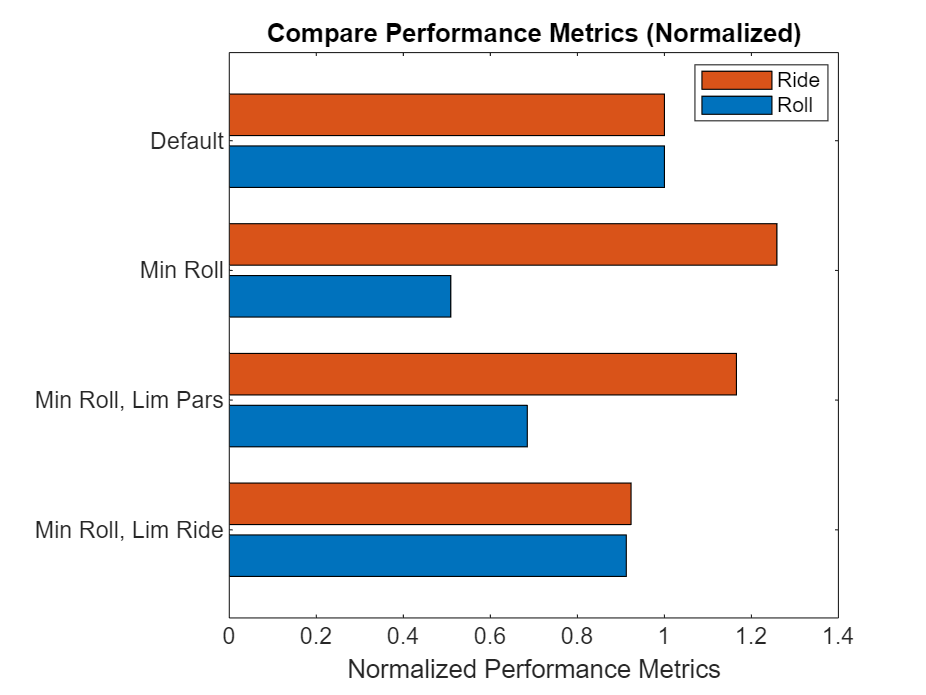


[responseComparison,simResponseTable,predErrTable] = validateOptimSol(solutionsTable,...
    solIdx,paramsAllDef,designVarNames,mdl,Vehicle,parTableVal_trim,predResponseTable,simResponseTable,predErrTable);

Plotting predicted and simulated performance metrics show good agreement.

suspOpt_Optimize_Design_plot_MetricPredAndSim(responseComparison)

### Adding a Nonlinear Constraint

So far, the optimization problems have only considered the roll metric.  But the AI surrogate model also predicts the ride metric.

Check how the design solution of the previous problem performs with respect to ride metric.

ride2 = predResponseTable.("RideMetric")(2)

1 parameter sets submitted, 1 obey parameter constraints.
 
 
1 simulations completed in 24.5696 seconds.
 
Of 1 tests, 1 were valid.


responseComparison = 4×3 table
                   predResponseTable                        simResponseTable                predErrTable        
    ________________________________________________    ________________________    ____________________________

        Description         RideMetric    RollMetric    RideMetric    RollMetric    Ride % Error    Roll % Error
    ____________________    __________    __________    __________    __________    ____________    ____________
                                                                                                                
    "Default"                 1.0263        0.14033       1.026

Suppose this ride metric value is not low enough to meet requirements, and that the ride metric must meet the following requirement:

rideMetric <= 0.95

The optimization problem can be modified to include this requirement as a nonlinear constraint.

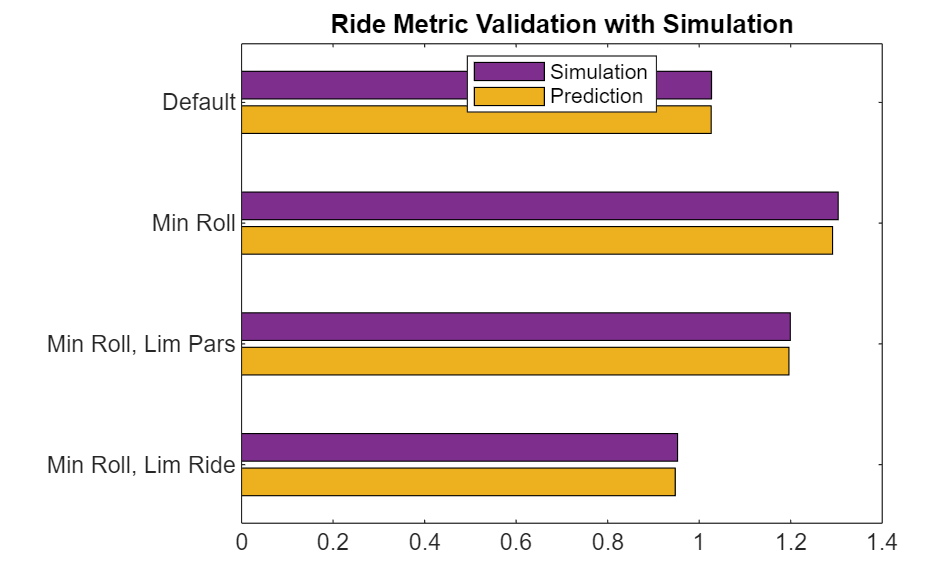

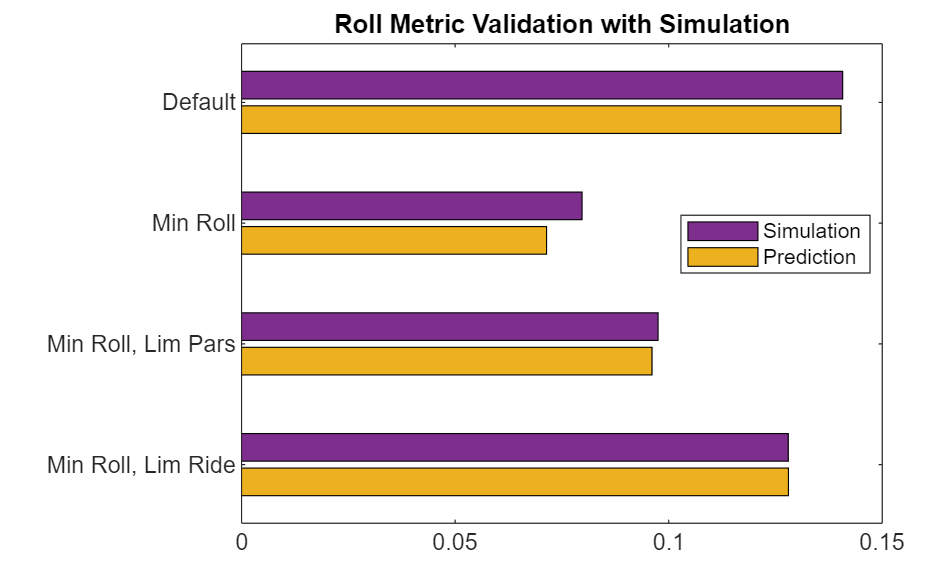

% Copy the previous problem for modification.
rideConProb = rollProb;


% Add the requirement on ride metric as a nonlinear constraint.
rideConProb.Constraints.rideMetric = ridePredict <= 0.95;

Solve the new optimization problem.

tic
[solution_rideCon,optRoll_rideCon,exitFlag_rideCon] = solve(rideConProb,initialPoint,...
    "Solver",chosenSolver,"Options",options_roll)
toc

Add the new solution to the solutions table and predicted responses tables.

% Specify short description of this optimization problem for the table
descriptText = 'Min Roll, Lim Ride';

% Call helper function to add the solution and response values to the
% tables
[solutionsTable,predResponseTable] = addSolResptoTables(solution_rideCon,descriptText,solutionsTable,predResponseTable,designVarNames,...
    responseVarNames,rollPredict,ridePredict)

Plot resulting design parameter values relative to the defaults

suspOpt_Optimize_Design_plot_ParamAndDefault(solutionsTable(end,:))

Plot normalized predicted performance metrics for comparison.

The ride metric satisfies the requirement specified by the constraint, while the performance decreased with respect to the roll metric.  There's a trade-off between the two metrics.


Solving problem using patternsearch.
patternsearch stopped because the mesh size was less than options.MeshTolerance.


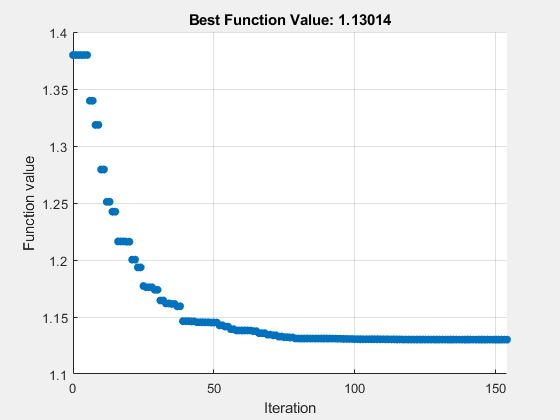

solution_multiResp = struct with fields:
    designVars: [0.1750 0.1550 -0.2500 0.5000 0.1500 0.6560 0.1000 0.3000 0.1000 0.6500]


optWgtObjPred_multiResp = 1.1301

exitFlag_multiResp =     SolverConvergedSuccessfully


suspOpt_Optimize_Design_plot_MetricAndDefault(predResponseTable);

Validate with simulation.

solIdx = 4;

Elapsed time is 7.823252 seconds.



[responseComparison,simResponseTable,predErrTable] = validateOptimSol(solutionsTable,...
    solIdx,paramsAllDef,designVarNames,mdl,Vehicle,parTableVal_trim,predResponseTable,simResponseTable,predErrTable);

Plotting predicted and simulated performance metrics shows good agreement.

suspOpt_Optimize_Design_plot_MetricPredAndSim(responseComparison)

### Combining Multiple Responses in Single Objective Function

Instead of using one response for the objective and another as as constraint, multiple responses can be combined into a single objective function.  The optimization solver will optimize both responses at the same time.

% In this case, the new problem is derived from a problem without the
% constraint on ride metric, but users can choose to include the
% constraint if desired
multiRespProb = rollProb;

solutionsTable = 5×11 table
        Description         HP_A1_Ro_Inbz    HP_A1_Ro_Outz    HP_A1_AR_Inbx    HP_A2_UA_Outz    HP_A2_LA_inRz    HP_A2_LA_Outy    HP_A2_LA_Outz    HP_A2_AR_Inbx    HP_A2_AR_Outx    HP_A2_AR_Outy
    ____________________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "Default"                    0.205           0.185              -0.3             0.45           0.15              0.706             0.15            0.3               0.05              0.6   
    "Min Rol

predResponseTable = 5×3 table
        Description         RideMetric    RollMetric
    ____________________    __________    __________

    "Default"                 1.0263        0.14033 
    "Min Roll"                1.2915       0.071414 
    "Min Roll, Lim Pars"      1.1962       0.096094 
    "Min Roll, Lim Ride"     0.94767        0.12804 
    "Min (Roll+Ride)"         1.1746        0.09647 


Optionally, use scale factors to adjust for differences in scale of individual objectives.  Here, the response values from the solution of the modified design space problem are used.

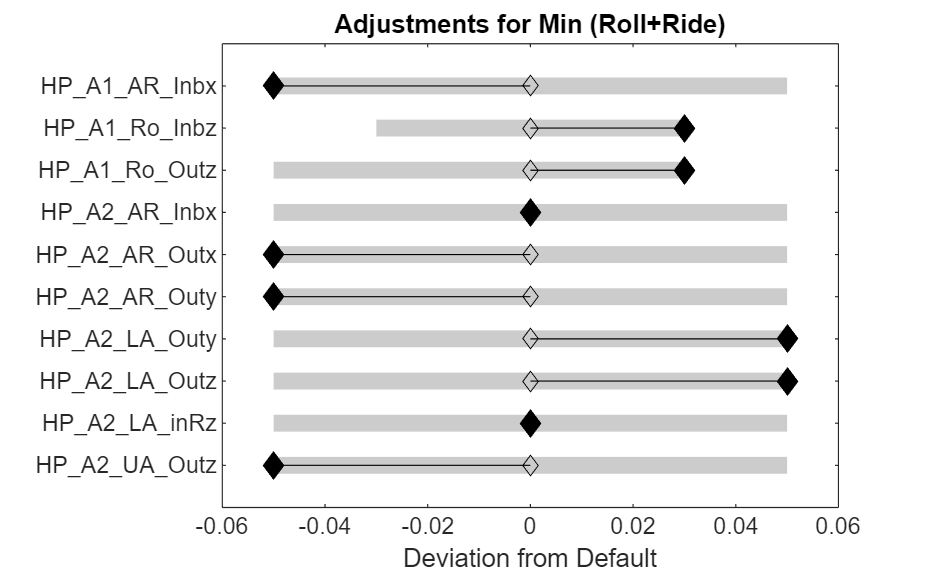

sclRoll = predResponseTable{2,"RollMetric"};

sclRide = predResponseTable{2,"RideMetric"};

When combining the responses into the single objective function, use weight factors to indicate the relative importance of each response.  Here, equal weigh factors are used.

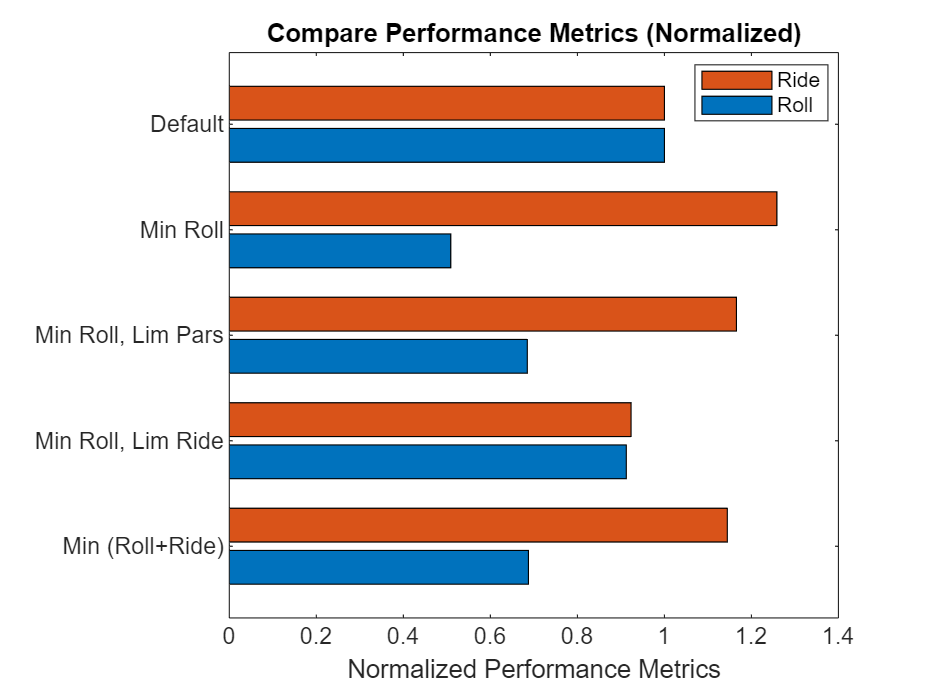

wtRoll = 0.5;

wtRide = 0.5;

Define the combined objective expression and assign it to the problem.

multiRespProb.Objective = wtRoll/sclRoll*rollPredict + ...
    wtRide/sclRide*ridePredict;

Solve the problem.

tic
[solution_multiResp,optWgtObjPred_multiResp,exitFlag_multiResp] = solve(multiRespProb,initialPoint,...

1 parameter sets submitted, 1 obey parameter constraints.
 
 
1 simulations completed in 23.6061 seconds.
 
Of 1 tests, 1 were valid.


responseComparison = 5×3 table
                   predResponseTable                        simResponseTable                predErrTable        
    ________________________________________________    ________________________    ____________________________

        Description         RideMetric    RollMetric    RideMetric    RollMetric    Ride % Error    Roll % Error
    ____________________    __________    __________    __________    __________    ____________    ____________
                                                                                                                
    "Default"                 1.0263        0.14033       1.026

    "Solver",chosenSolver,"Options",options_roll)
toc

Update the solutions and predicted reponses tables.

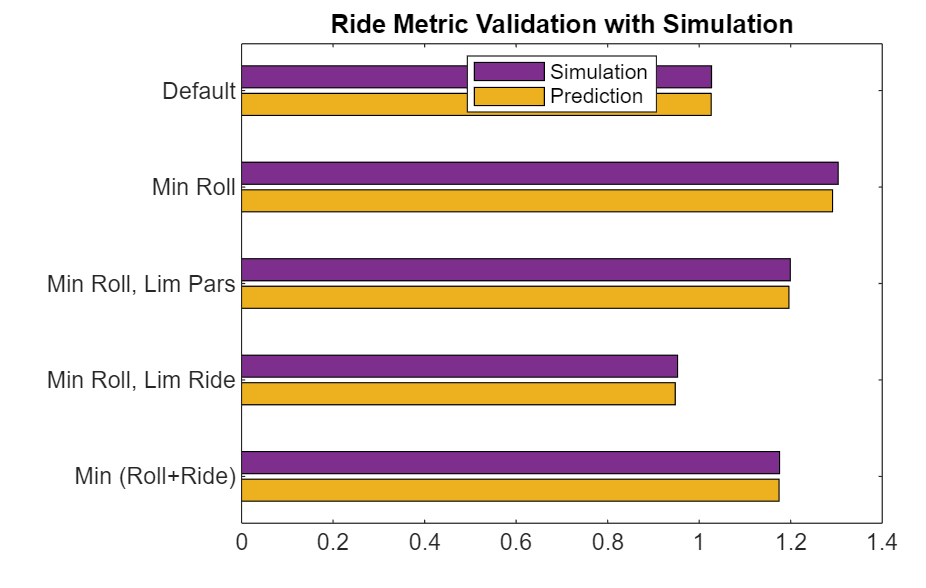

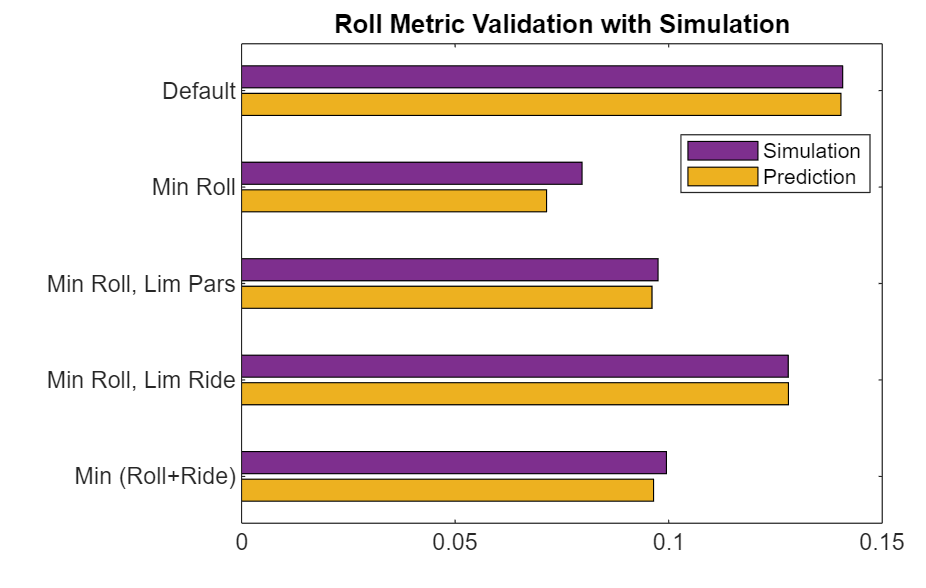

% Specify short description of this optimization problem for the table

descriptText = 'Min (Roll+Ride)';

% Call helper function to add the solution and response values to the
% tables
[solutionsTable,predResponseTable] = addSolResptoTables(solution_multiResp,descriptText,solutionsTable,predResponseTable,designVarNames,...
    responseVarNames,rollPredict,ridePredict)

Plot resulting design parameter values relative to the defaults.

suspOpt_Optimize_Design_plot_ParamAndDefault(solutionsTable(end,:))

Plot normalized predicted performance metrics for comparison.

Even with both metrics included in the combined objective function, the optimization algorithm finds it beneficial to significantly reduce the roll metric at the expense of the ride metric.  More priority can be placed on reducing the ride metric by adjusting the weight factors in the objective function.

suspOpt_Optimize_Design_plot_MetricAndDefault(predResponseTable);

Validate with simulation.

solIdx = 5;

[responseComparison,simResponseTable,predErrTable] = validateOptimSol(solutionsTable,...
    solIdx,paramsAllDef,designVarNames,mdl,Vehicle,parTableVal_trim,predResponseTable,simResponseTable,predErrTable);

Plotting predicted and simulated performance metrics show good agreement.

suspOpt_Optimize_Design_plot_MetricPredAndSim(responseComparison)

### Multi-Objective Optimization

The approach above of combining multiple responses into a single objective function identifies a single solution on the Pareto front.  The location of the solution along the Pareto front depended on the weight and scale factors used for each response.

A more general approach is to use a multi-objective optimization algorithm to resolve the full Pareto front, fully characterizing the optimal trade-off between the objectives.

To define a multi-objective problem, define a separate objective for each response.  Here, the objectives are to minimize the roll metric and minimize the ride metric.

% Create a copy of the optimization problem for modification
multiObjProb = multiRespProb;

autosolverMO = "gamultiobj"

validsolversMO = 1×2 string array
    "gamultiobj"    "paretosearch"



% Define multiple objectives separately in the problem
multiObjProb.Objective = [];
multiObjProb.Objective.roll = rollPredict;
multiObjProb.Objective.ride = ridePredict;

multiObjProb.ObjectiveSense.roll = 'min';
multiObjProb.ObjectiveSense.ride = 'min';

Check which solvers are applicable for this multi-objective problem.

[autosolverMO,validsolversMO] = solvers(multiObjProb)

Global Optimization Toolbox provides two multi-objective solvers: gamultiobj and paretosearch.  gamultiobj tends to sample the Pareto front more fully with a better spread of solutions, so it is used here.  While gamultiobj uses more function evaluations, this is acceptable, since the fast-running AI surrogate model is providing the objective values.

% Choose solver, set additional options
chosenSolverMO = "gamultiobj";


Solving problem using gamultiobj.

Multi-objective optimization:
10 Variables
2 Linear inequality constraints

Options:
CreationFcn:       @gacreationlinearfeasible
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           200                 1                 1
    2           400        0.00729739          0.356535
    3           600         0.0061213          0.912128
    4           800        0.00451589          0.886976
    5          1000         0.0054303          0.915285
    6          1200        0.00623723          0.637429
    7          1400        0.00463196          0.462103
    8          1600        0.00379048          0.910805
    9          1800        0.00422196          0.576423
   10          2000        0.00484691          0.759399
   11          2200        0.004

solution_multiObj =   1×70 OptimizationValues vector with properties:

   Variables properties:
         designVars: [10×70 double]

   Objective properties:
               roll: [0.1071 0.1482 0.1649 0.1764 0.1251 0.1266 0.1182 0.1080 0.1454 0.1442 0.1034 0.1821 0.1139 0.1516 0.1093 0.1058 0.1219 0.1504 0.1621 0.1061 0.1097 0.1106 0.1044 0.1060 0.1137 0.1792 0.1040 0.1068 0.1041 0.1112 … ] (1×70 double)
               ride: [1.0998 0.8871 0.8702 0.8595 0.9771 0.9700 1.0187 1.0952 0.8924 0.8947 1.1446 0.8575 1.0471 0.8836 1.0856 1.1192 0.9932 0.8847 0.8734 1.1114 1.0802 1.0728 1.1261 1.1154 1.0508 0.8584 1.1373 1.1071 1.1328 1.0678 … ] (1×70 double)

   Constraints properties:
    tireRodAngleMin: [-0.0871 -0.0403 -0.0291 -0.0268 -0.0736 -0.0715 -0.0690 -0.0804 -0.0449 -0.0479 -0.0890 -0.0192 -0.0677 -0.0375 -0.0716 -0.0799 -0.0642 -0.0373 -0

fval_multiObj =     0.1071    0.1482    0.1649    0.1764    0.1251    0.1266    0.1182    0.1080    0.1454    0.1442    0.1034    0.1821    0.1139    0.1516    0.1093    0.1058    0.1219    0.1504    0.1621    0.1061    0.1097    0.1106    0.1044    0.1060    0.1137    0.1792    0.1040    0.1068    0.1041    0.1112    0.1233    0.1388    0.1375    0.1271    0.1049    0.1288    0.1335    0.1398    0.1039    0.1164    0.1257    0.1205    0.1168    0.1606    0.1408    0.1284    0.1329    0.1310    0.1361    0.1638
    1.0998    0.8871    0.8702    0.8595    0.9771    0.9700    1.0187    1.0952    0.8924    0.8947    1.1446    0.8575    1.0471    0.8836    1.0856    1.1192    0.9932    0.8847    0.8734    1.1114    1.0802    1.0728    1.1261    1.1154    1.0508    0.8584    1.1373    1.1071    1.1328    1.0678    0.9863    0.9101    0.9145    0.9639    1.1204    0.9535    0.9308    0.9069    1.1429    1.0317    0.9731    1.0023    1.0280    0.8750    0.9043    0.9592    0.9356    0.9440   

exitFlag_multiObj =     SolverConvergedSuccessfully


Elapsed time is 87.142496 seconds.


% Could use PlotFcn="gaplotpareto" to plot Pareto front as solver
% progresses.  But for efficiency, the Pareto front is plotted after the
% solver completes instead.
optionsMO = optimoptions(chosenSolverMO,"Display","iter");

Solve the problem.

tic
[solution_multiObj,fval_multiObj,exitFlag_multiObj] = solve(multiObjProb,initialPoint,...
    "Solver",chosenSolverMO,"Options",optionsMO)
toc

Plot the Pareto front, which provides the set of solution points with the optimal trade-off between the objectives.

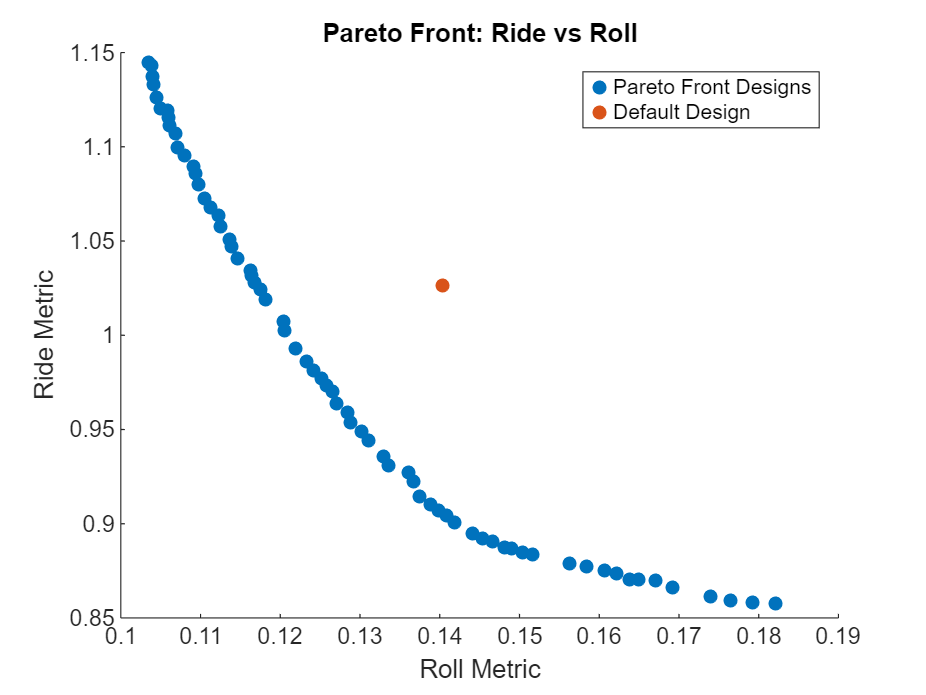

figure
scatter(fval_multiObj(1,:),fval_multiObj(2,:),'filled');
hold on

scatter(predResponseTable.RollMetric(1),predResponseTable.RideMetric(1),'filled')
hold off
title('Pareto Front: Ride vs Roll')
xlabel('Roll Metric')
ylabel('Ride Metric')
legend('Pareto Front Designs','Default Design')

Identify one or more points of interest from the Pareto front, to validate with simulation.  For example, identify the Pareto front point that gives the lowest ride metric value, while the roll metric is less than 0.14.

(This would often be done interactively from the Pareto front plot, but is done programmatically here for automation purposes.)

% Find indices where the first row is less than 0.14
validIndices = find(fval_multiObj(1, :) < 0.14);

% Extract the second row values at those indices
secondRowValues = fval_multiObj(2, validIndices);

% Find the index of the minimum value in the second row values
[~, minIndex] = min(secondRowValues);

% Get the corresponding column index in fval_multiObj
columnIndex = validIndices(minIndex);

% Store the solution point of interest, as a struct for consistency with
% solutions from previous problems
solution_multiObj_pt = solution_multiObj(columnIndex);
solution_multiObj_ptStruct.designVars = solution_multiObj_pt.designVars';

Add point to solutions and predicted responses tables tables.

% Specify short description of this optimization problem for the table
descriptText = 'Min Roll & Min Ride';

% Call helper function to add the solution and response values to the
% tables
[solutionsTable,predResponseTable] = addSolResptoTables(solution_multiObj_ptStruct,descriptText,solutionsTable,predResponseTable,designVarNames,...

solutionsTable = 6×11 table
         Description         HP_A1_Ro_Inbz    HP_A1_Ro_Outz    HP_A1_AR_Inbx    HP_A2_UA_Outz    HP_A2_LA_inRz    HP_A2_LA_Outy    HP_A2_LA_Outz    HP_A2_AR_Inbx    HP_A2_AR_Outx    HP_A2_AR_Outy
    _____________________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________    _____________

    "Default"                     0.205            0.185             -0.3             0.45             0.15            0.706             0.15            0.3               0.05              0.6   
    "Min 

predResponseTable = 6×3 table
         Description         RideMetric    RollMetric
    _____________________    __________    __________

    "Default"                  1.0263        0.14033 
    "Min Roll"                 1.2915       0.071414 
    "Min Roll, Lim Pars"       1.1962       0.096094 
    "Min Roll, Lim Ride"      0.94767        0.12804 
    "Min (Roll+Ride)"          1.1746        0.09647 
    "Min Roll & Min Ride"     0.90695        0.13982 


    responseVarNames,rollPredict,ridePredict)

Plot resulting design parameter values relative to the defaults.

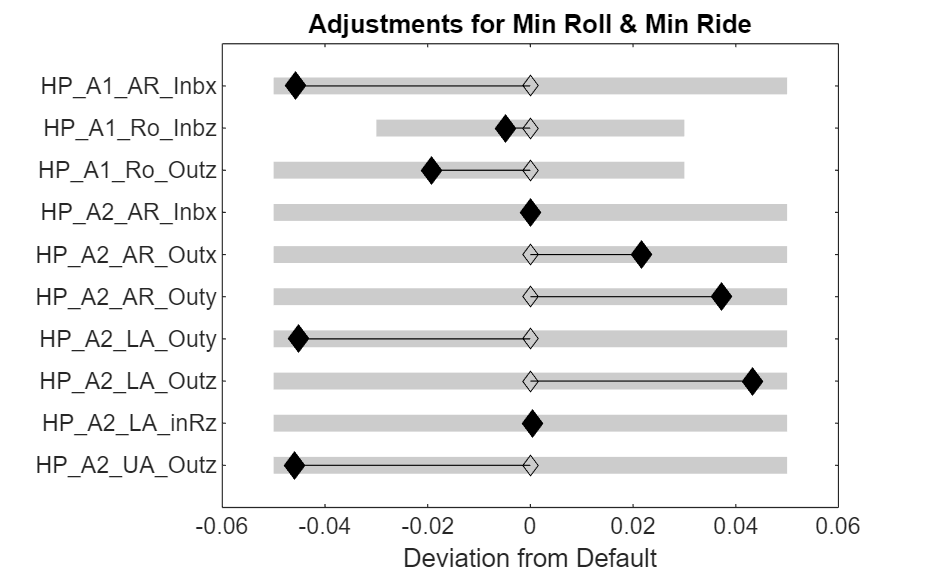

suspOpt_Optimize_Design_plot_ParamAndDefault(solutionsTable(end,:))

Plot normalized predicted performance metrics for comparison.

The design point that was arbitrarily selected from the Pareto front has a lower ride metric value, but a roll metric value similar to the default design.

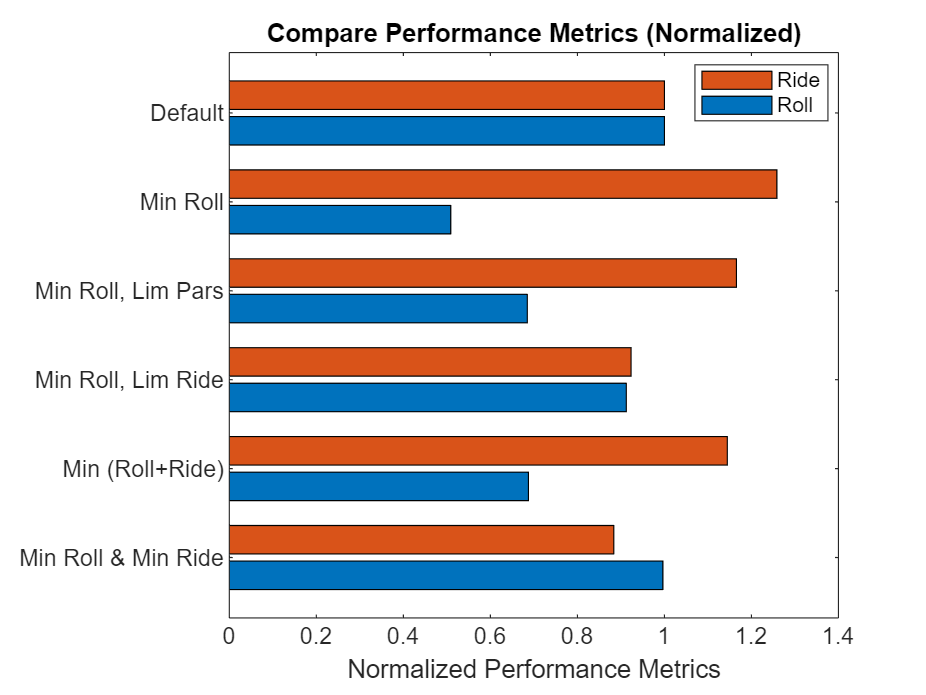

suspOpt_Optimize_Design_plot_MetricAndDefault(predResponseTable);

Validate with simulation.


solIdx = 6;

[responseComparison,simResponseTable,predErrTable] = validateOptimSol(solutionsTable,...
    solIdx,paramsAllDef,designVarNames,mdl,Vehicle,parTableVal_trim,predResponseTable,simResponseTable,predErrTable);

1 parameter sets submitted, 1 obey parameter constraints.
 
 
1 simulations completed in 26.5423 seconds.
 
Of 1 tests, 1 were valid.


responseComparison = 6×3 table
                    predResponseTable                        simResponseTable                predErrTable        
    _________________________________________________    ________________________    ____________________________

         Description         RideMetric    RollMetric    RideMetric    RollMetric    Ride % Error    Roll % Error
    _____________________    __________    __________    __________    __________    ____________    ____________
                                                                                                                 
    "Default"                  1.0263        0.14033      

Plotting predicted and simulated performance metrics shows good agreement.

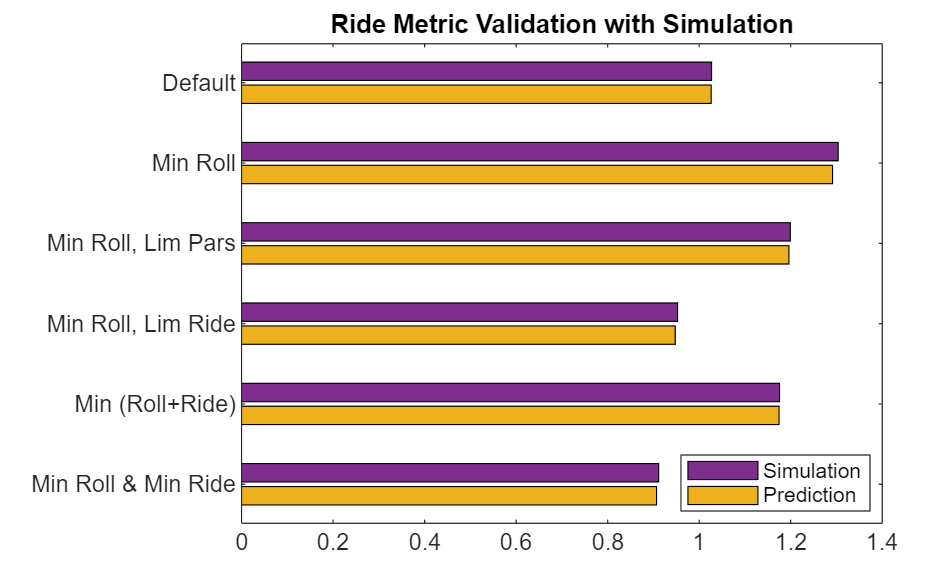

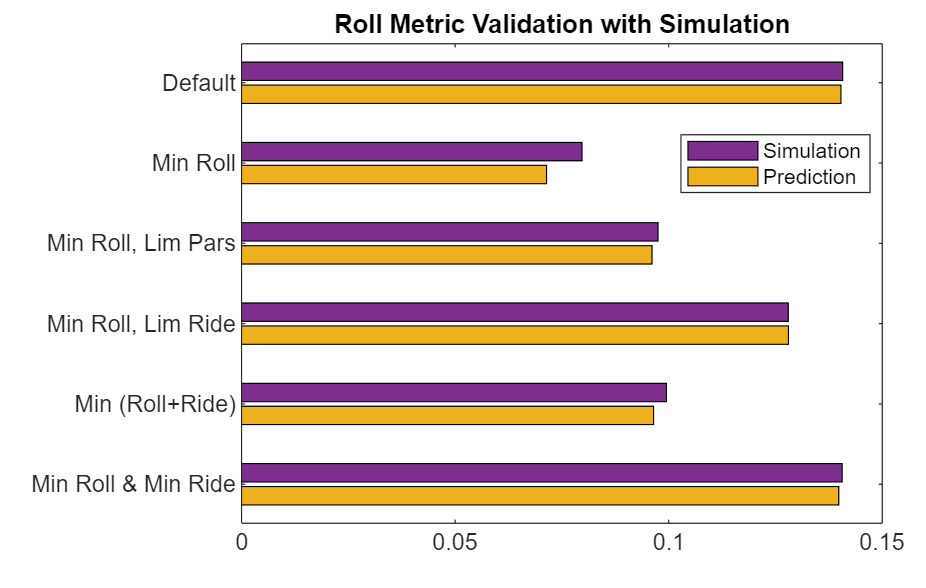

suspOpt_Optimize_Design_plot_MetricPredAndSim(responseComparison)

As seen in this example, applying optimization algorithms with AI models can be used to rapidly identify new designs solutions for multiple design scenarios with different requirements.  The AI models enable the optimization algorithms to complete very quickly, allowing the exploration of different what-if scenarios.  Simulation is used to verify the solutions identified by the AI-based optimization process.